# EL2520 Computer Exercise 2

## 3.1 Poles, zeros and RGA

s = tf('s');
% sys = minphase;
sys = nonminphase; % 3.1.6


### 3.1.1

% transfer function
A = sys.A;
B = sys.B;
C = sys.C;
D = sys.D;

I = eye(size(A,1));

G = C*inv(s*I-A)*B+D; % 2x2 trans. func.

for i = 1:2
    for j = 1:2
        X = ['G(',num2str(i), ',', num2str(j), ') = '];
        disp(X)
        G(i,j)
        poles = pole(G(i,j))
        zeros = tzero(G(i,j))
    end
end

G(1,1) = 



ans =
 
    0.02088
  -----------
  s + 0.05106
 
Continuous-time transfer function.



poles = -0.0511


zeros =

  0×1 empty double column vector



G(1,2) = 



ans =
 
          0.002586
  -------------------------
  s^2 + 0.1369 s + 0.004382
 
Continuous-time transfer function.



poles =    -0.0858
   -0.0511



zeros =

  0×1 empty double column vector



G(2,1) = 



ans =
 
          0.003163
  -------------------------
  s^2 + 0.1378 s + 0.004265
 
Continuous-time transfer function.



poles =    -0.0909
   -0.0469



zeros =

  0×1 empty double column vector



G(2,2) = 



ans =
 
    0.01808
  -----------
  s + 0.04692
 
Continuous-time transfer function.



poles = -0.0469


zeros =

  0×1 empty double column vector



### 3.1.2

% poles and zeros
allpoles = pole(G)

allpoles =    -0.0511
   -0.0909
   -0.0469
   -0.0858
   -0.0511
   -0.0469


allzeros = tzero(G)

allzeros =    -0.2356
    0.0589
   -0.0511
   -0.0469



syspoles = pole(sys)

syspoles =    -0.0511
   -0.0469
   -0.0858
   -0.0909


syszeros = tzero(sys)

syszeros =     0.0589
   -0.2356


### 3.1.3

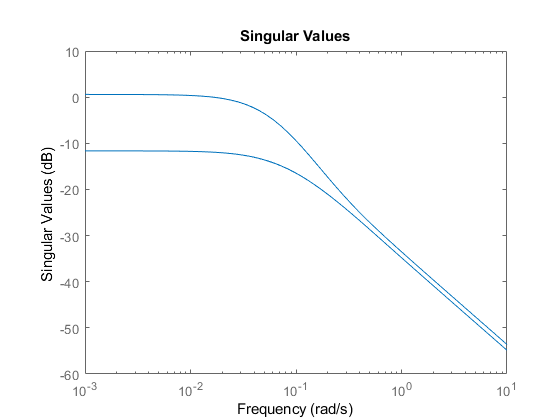

% singular values
sigma(sys)

hinfn = hinfnorm(sys)

hinfn = 1.0702

### 3.1.4

% RGA
rga = minreal(G*transpose(inv(G)));
rga_zero = freqresp(rga,0)

rga_zero =     0.6806    0.2214
   -0.2086    1.4015


### 3.1.5

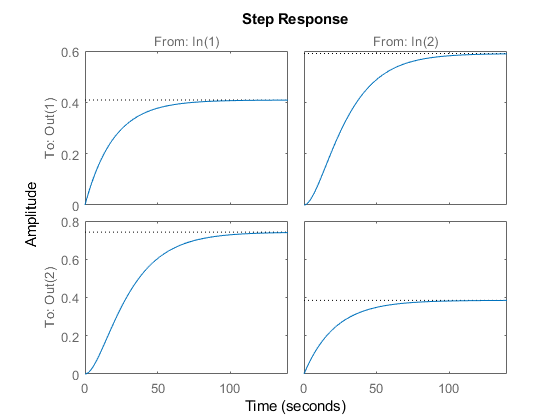

% step
step(G)